# Steady Exchange Flow

close all, clear, clc
Grid.xmin = 0; Grid.xmax = 50; Grid.Nx = 50;
Grid = build_grid(Grid);
[D,G,~,I,M] = build_ops(Grid);
If = speye(Grid.Nf); % Nf by Nf identity

## Dirichlet BC's

We can solve this probem by prescribing the values of the functions at the top and bottom.

% Solve mod. Helmholtz equations 
L_h  = -D*G+I;  fs_h = Grid.xc; 
% flux_h = @(h) -G*h;
% res_h = @(h,cell) L_h(cell,:)*h - fs_h(cell); 

% Define BC's
BC.h.dof_dir   = [Grid.dof_xmin;Grid.dof_xmax];
BC.h.dof_f_dir = [Grid.dof_f_xmin;Grid.dof_f_xmax];
BC.h.g         = [Grid.xmin+Grid.dx/2;Grid.xmax-Grid.dx/2];
BC.h.dof_neu   = [];
BC.h.dof_f_neu = [];
BC.h.qb        = [];

[B_h,N_h,fn_h] = build_bnd(BC.h,Grid,I);

%% Solve boundary value problem
hD = solve_lbvp(L_h,fs_h+fn_h,B_h,BC.h.g,N_h);
qD = comp_flux_helm(D,G,If,I,hD,fs_h,Grid,BC.h);
% qD = comp_flux_gen(flux_h,res_h,hD,Grid,BC.h);
pD = hD-Grid.xc;

## Poisson equation

L_u  = -D*G; % system matrix
fs_u = pD;   % r.h.s.
% flux_u = @(u) -G*u;
% res_u = @(u,cell) L_u(cell,:)*u - fs_u(cell); 

% Define BC's
BC.u.dof_dir   = [Grid.dof_xmin;Grid.dof_xmax];
BC.u.dof_f_dir = [Grid.dof_f_xmin;Grid.dof_f_xmax];
BC.u.g         = [Grid.xmax-Grid.dx/2;Grid.xmin+Grid.dx/2];
BC.u.dof_neu   = [];
BC.u.dof_f_neu = [];
BC.u.qb        = [];

[B_u,N_u,fn_u] = build_bnd(BC.u,Grid,I);

% Solve boundary value problem
uD = solve_lbvp(L_u,fs_u+fn_u,B_u,BC.u.g,N_u);
vD = comp_flux(D,If,G,uD,fs_u,Grid,BC.u);
% vD = comp_flux_gen(flux_u,res_u,uD,Grid,BC.h);

## Plotting

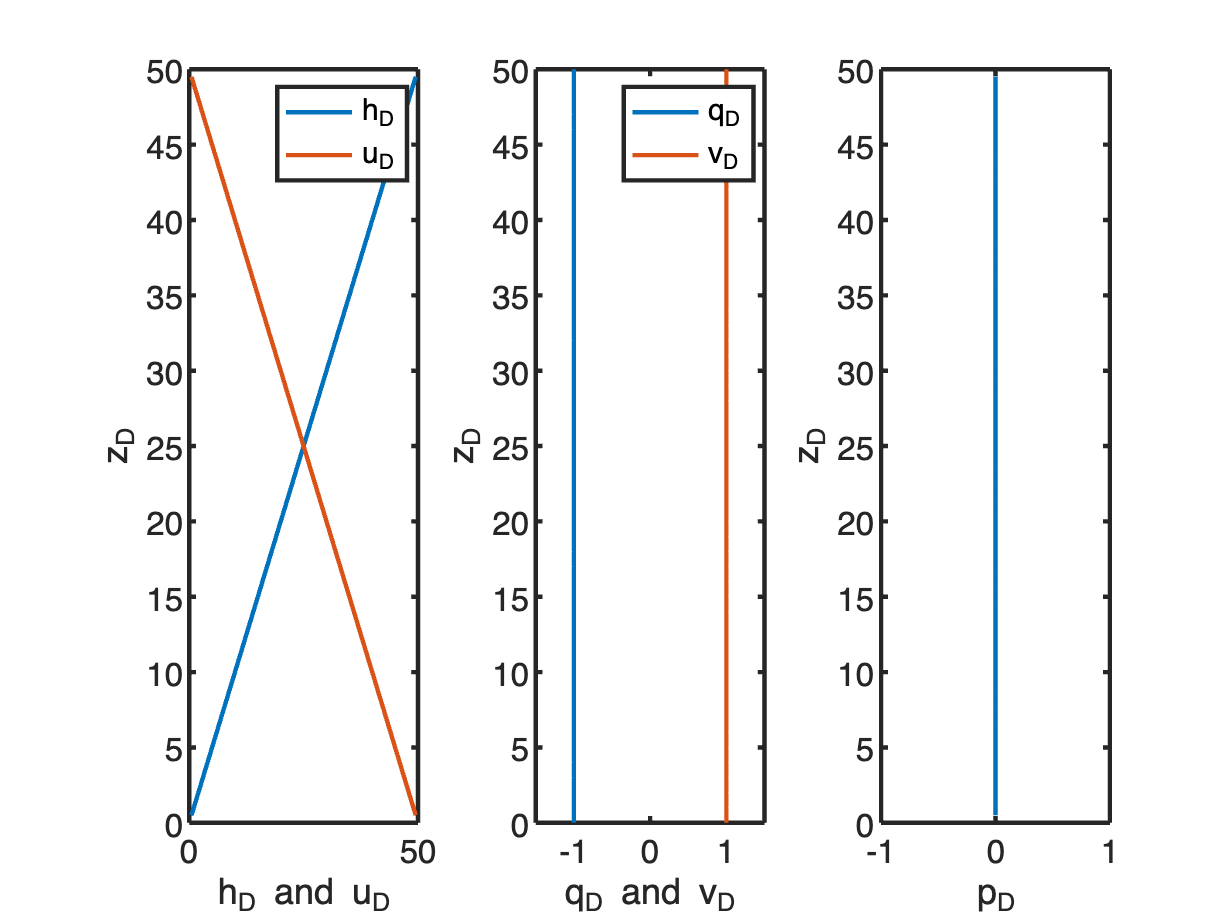

figure
subplot 131
plot(hD,Grid.xc,'linewidth',2), hold on
plot(uD,Grid.xc,'linewidth',2)
xlim([0 Grid.xmax])
xlabel 'h_D and u_D'
ylabel 'z_D'
legend('h_D','u_D')

subplot 132
plot(qD,Grid.xf,'linewidth',2), hold on
plot(vD,Grid.xf,'linewidth',2)
xlim([-1.5 1.5])
xlabel 'q_D and v_D'
ylabel 'z_D'
legend('q_D','v_D')

subplot 133
plot(pD,Grid.xc,'linewidth',2), hold on
xlim([-1 1])
xlabel 'p_D'
ylabel 'z_D'

## Neumann BC's

We can also solve this probem by prescribing the fluxes at the top and bottom.

## Modified Helmholtz equation

% Solve mod. Helmholtz equations 
L_h  = -D*G+I;  fs_h = Grid.xc; 
% flux_h = @(h) -G*h;
% res_h = @(h,cell) L_h(cell,:)*h - fs_h(cell); 

% Define BC's
BC.h.dof_dir   = [];
BC.h.dof_f_dir = [];
BC.h.g         = [];
BC.h.dof_neu   = [Grid.dof_xmin;Grid.dof_xmax];
BC.h.dof_f_neu = [Grid.dof_f_xmin;Grid.dof_f_xmax];
BC.h.qb        = [-1;1];

[B_h,N_h,fn_h] = build_bnd(BC.h,Grid,I);

%% Solve boundary value problem
hD = solve_lbvp(L_h,fs_h+fn_h,B_h,BC.h.g,N_h);
qD = comp_flux_helm(D,G,If,I,hD,fs_h,Grid,BC.h);
% qD = comp_flux_gen(flux_h,res_h,hD,Grid,BC.h);
pD = hD-Grid.xc;


## Poisson equation

L_u  = -D*G; % system matrix
fs_u = pD;   % r.h.s.
% flux_u = @(u) -G*u;
% res_u = @(u,cell) L_u(cell,:)*u - fs_u(cell); 

% Define BC's
BC.u.dof_dir   = [Grid.dof_xmin];
BC.u.dof_f_dir = [Grid.dof_f_xmin];
BC.u.g         = [Grid.xmax-Grid.dx/2];
BC.u.dof_neu   = [Grid.dof_xmax];
BC.u.dof_f_neu = [Grid.dof_f_xmax];
BC.u.qb        = [-1];

[B_u,N_u,fn_u] = build_bnd(BC.u,Grid,I);

% Solve boundary value problem

uD = solve_lbvp(L_u,fs_u+fn_u,B_u,BC.u.g,N_u);
vD = comp_flux(D,If,G,uD,fs_u,Grid,BC.u);
% vD = comp_flux_gen(flux_u,res_u,uD,Grid,BC.u);

## Plotting

figure
subplot 131
plot(hD,Grid.xc,'linewidth',2), hold on
plot(uD,Grid.xc,'linewidth',2)
xlim([0 Grid.xmax])
xlabel 'h_D and u_D'
ylabel 'z_D'
legend('h_D','u_D')

subplot 132
plot(qD,Grid.xf,'linewidth',2), hold on
plot(vD,Grid.xf,'linewidth',2)
xlim([-1.5 1.5])
xlabel 'q_D and v_D'
ylabel 'z_D'
legend('q_D','v_D')

subplot 133
plot(pD,Grid.xc,'linewidth',2), hold on
xlim([-1 1])
xlabel 'p_D'
ylabel 'z_D'